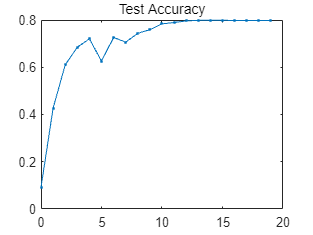

%%数据导入方式
% % load
% file=fullfile(pathname, filename);         % 导入.txt文件
% num=load(file) ;
% [m,n]=size(num);
% % importdata（）
% datatable = importdata(file);                %加载txt数据(只导入数据)
% data = datatable.data;                           %读取非元胞的数据
% % fopen+textscan
% file=fullfile(pathname, filename);      % 导入.txt文件
% f=fopen(file);    %以只读模式打开混合格式文本文件
% dt=textscan(f,'%s');         %采用textscan 读取数据
a = importdata('test_record.txt');
[r,c] = size(a);

%% 绘图
x = 0:1:(r-1);
plot(x,a(:,2),'.-')
title('Test Accuracy')

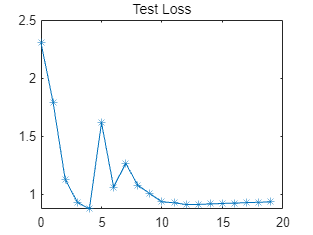


figure
plot(x,a(:,1),'*-')
title('Test Loss')